% s1
% reading audio and doing framing, overlap, windowing, and fft
[s1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s11.wav');
[check,dim] = size(s1);
y1 = zeros(check,1);
if dim > 1
    for i = 1:check
        if i == 1
            y1(i,1) = mean(s1(i,:));
        else
            y1(i,1) = mean(s1(i,:));
        end
    end
else
    y1 = s1;
end
sound(s1,Fs1)
% calculations for report
blockSize = 256;
sampleRate = Fs1

sampleRate = 12500

signalLength = length(y1(:,1))

signalLength = 20625

signalTime = length(y1(:,1)) / Fs1

signalTime = 1.6500

blockTime = blockSize / Fs1

blockTime = 0.0205

numBlocks = signalTime / blockTime

numBlocks = 80.5664

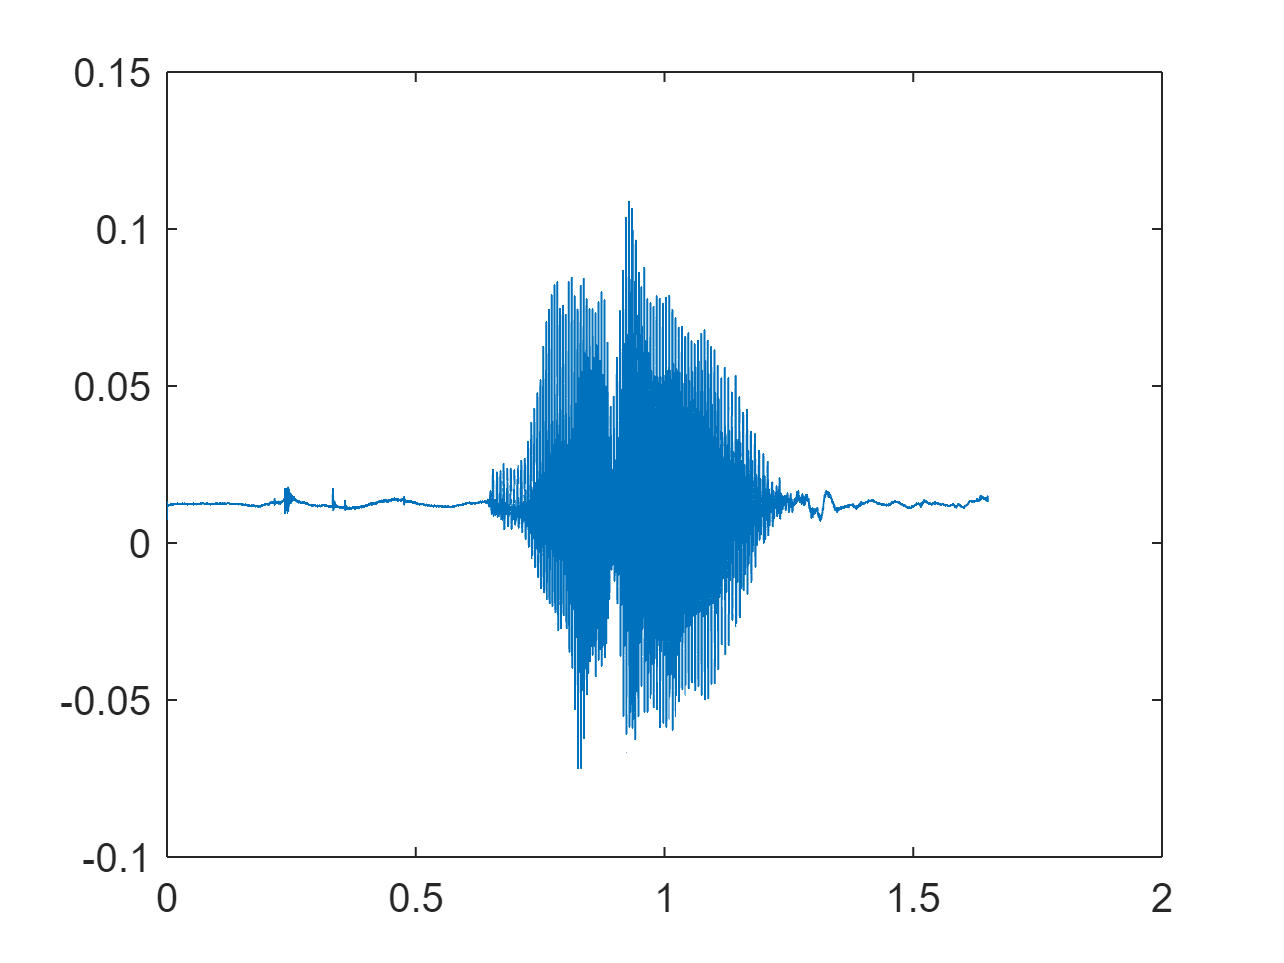

time = 0:1/Fs1:signalTime-(1/Fs1);
plot(time,y1)

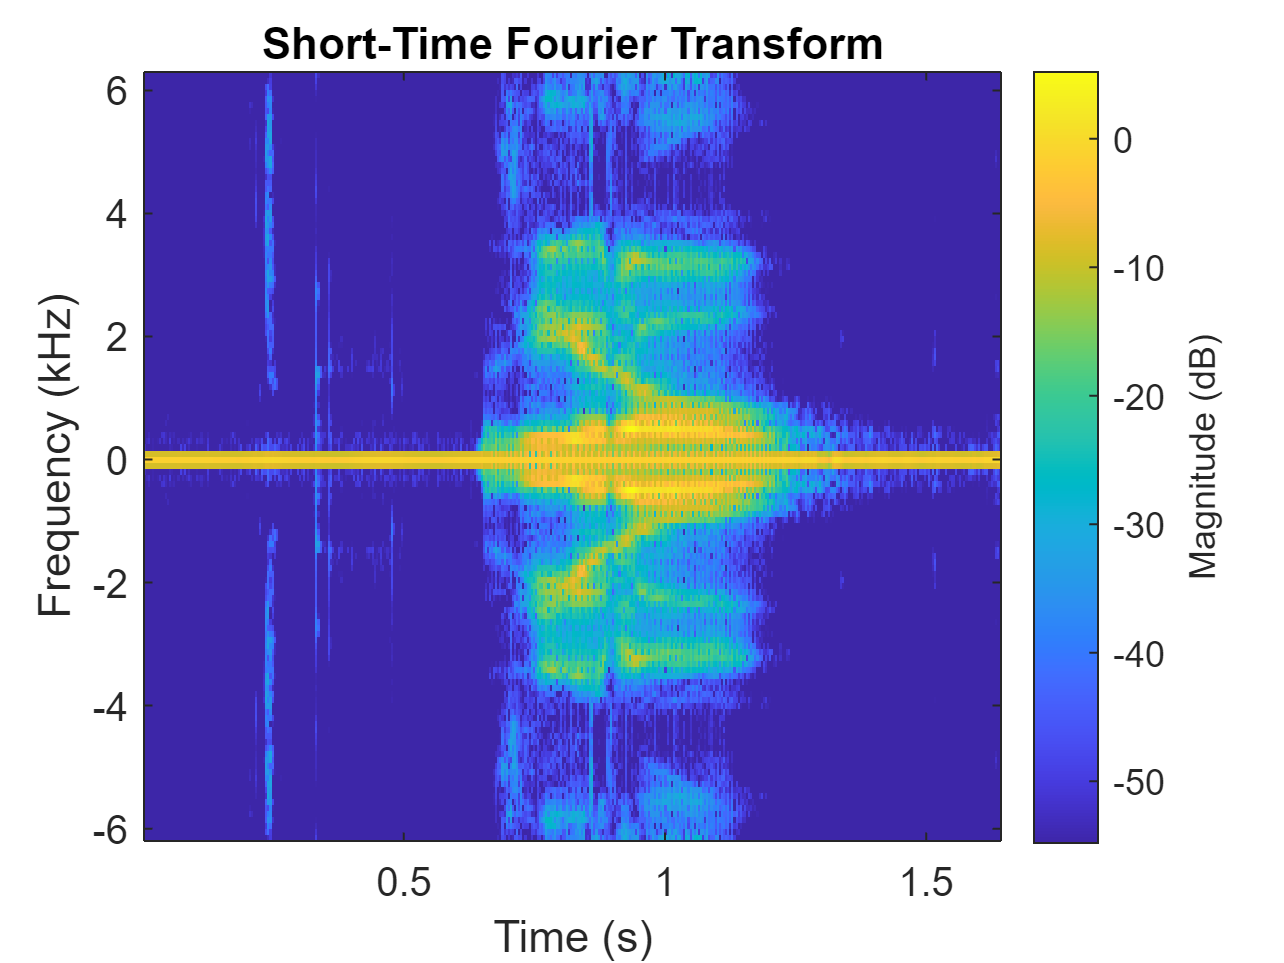

[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(128,'periodic'),OverlapLength=78,FFTLength=128)

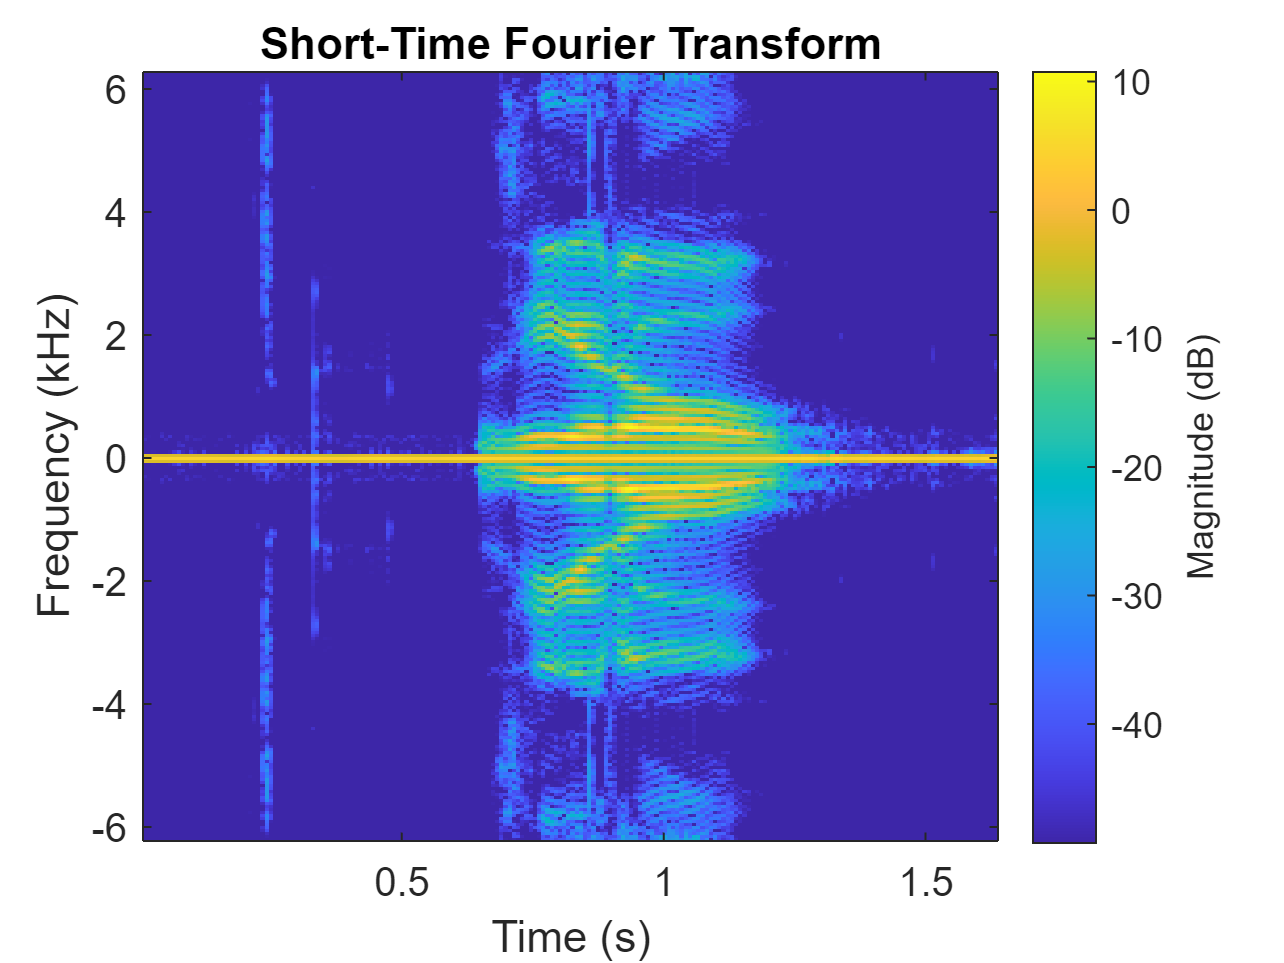

stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)

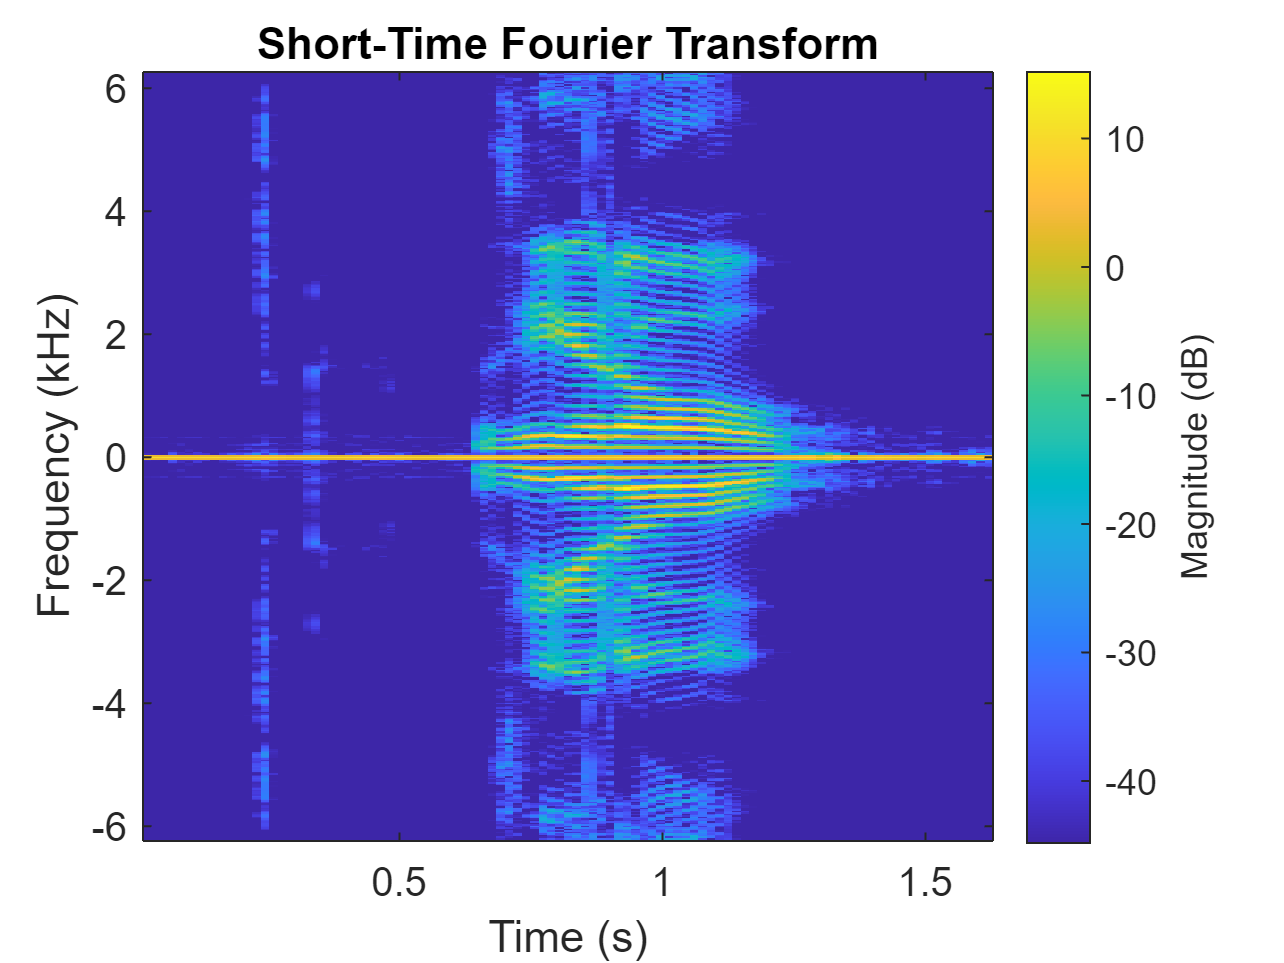

stft(y1,Fs1,Window=hamming(512,'periodic'),OverlapLength=312,FFTLength=512)

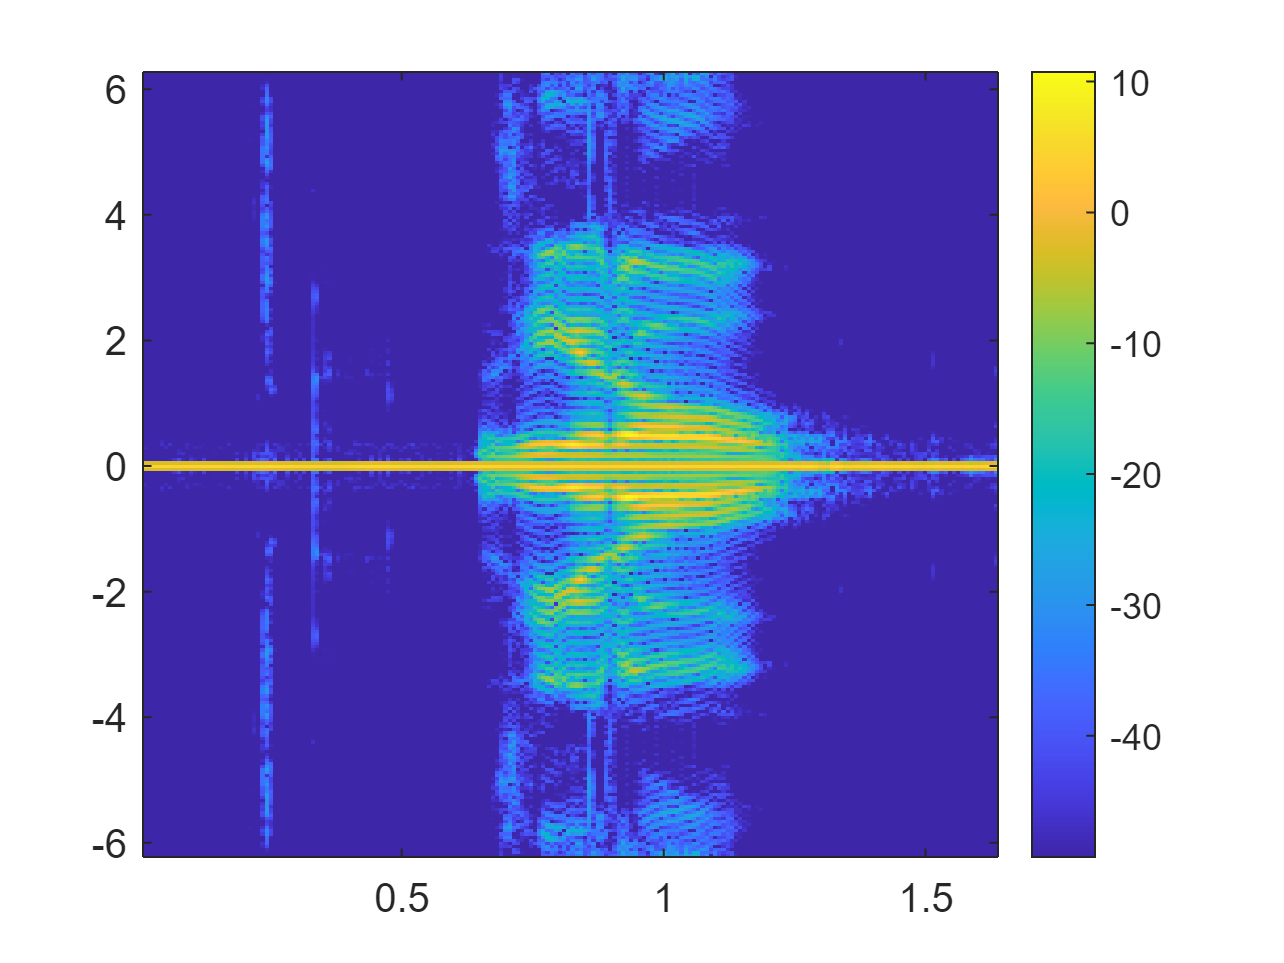

% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar

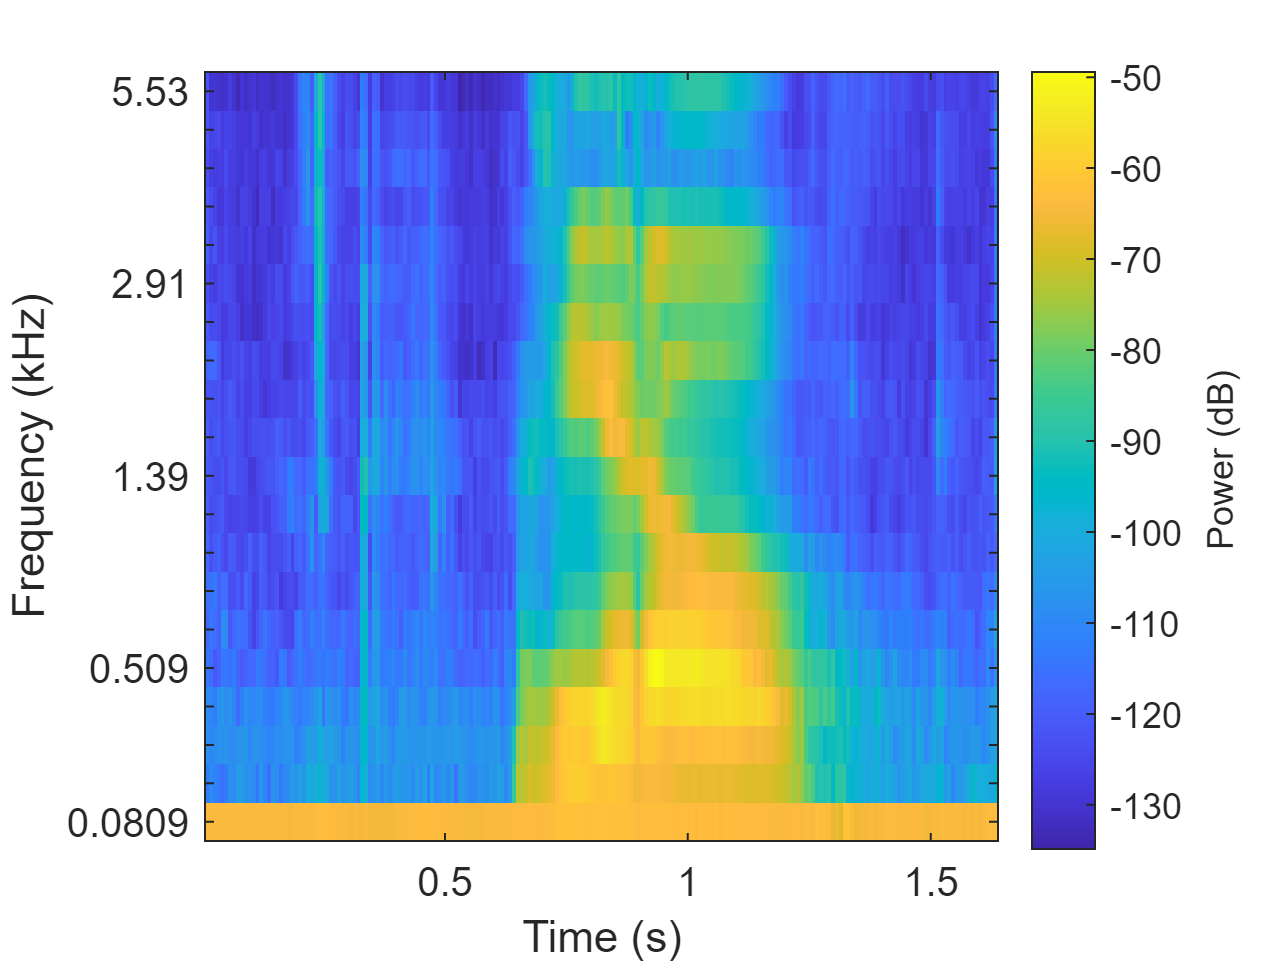

% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);

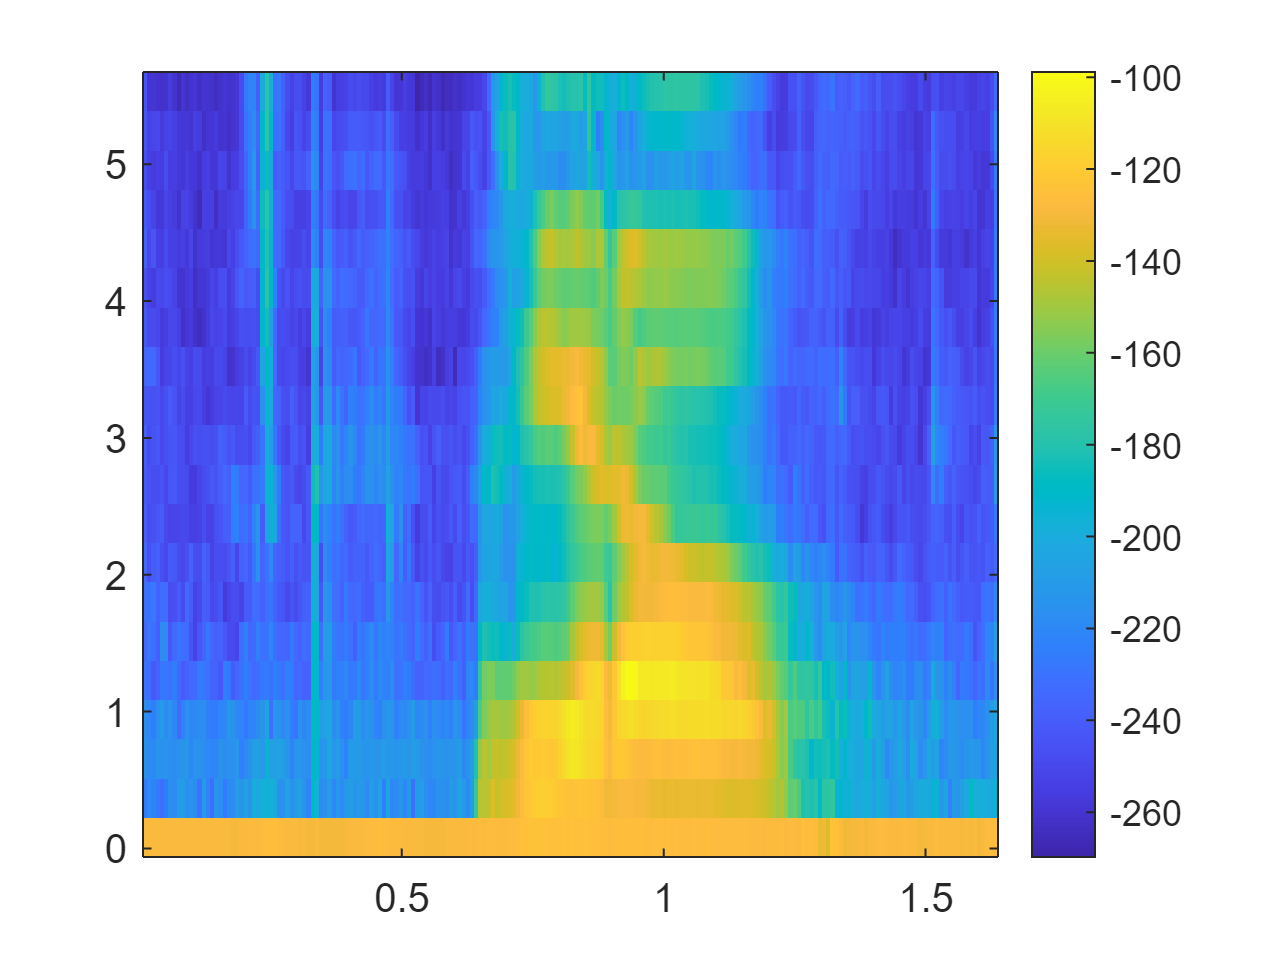

[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss));
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar

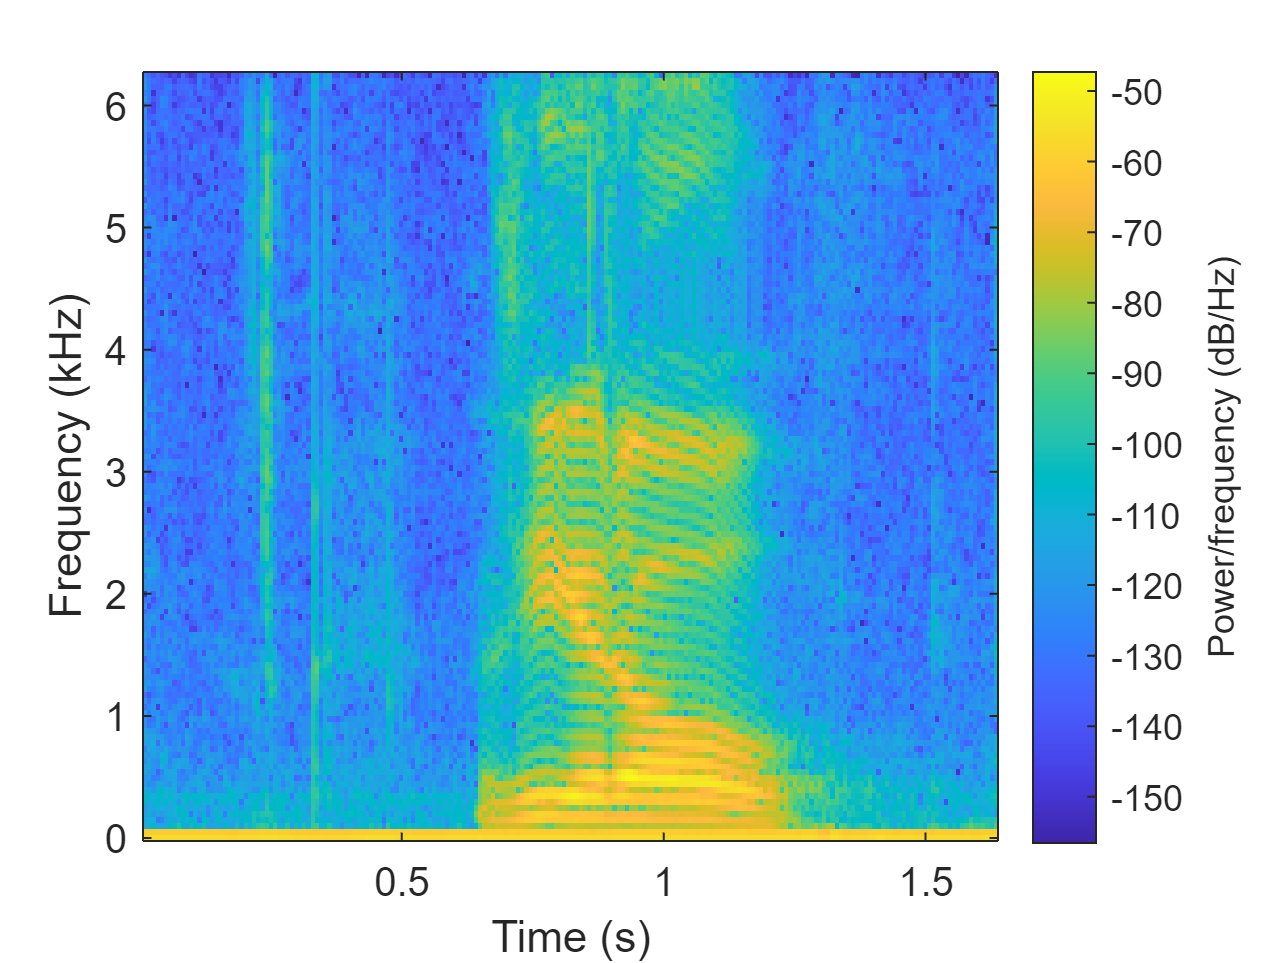

% end of mel spectrogram graph
spectrogram(y1',hamming(256,'periodic'),156,256,Fs1,'yaxis');

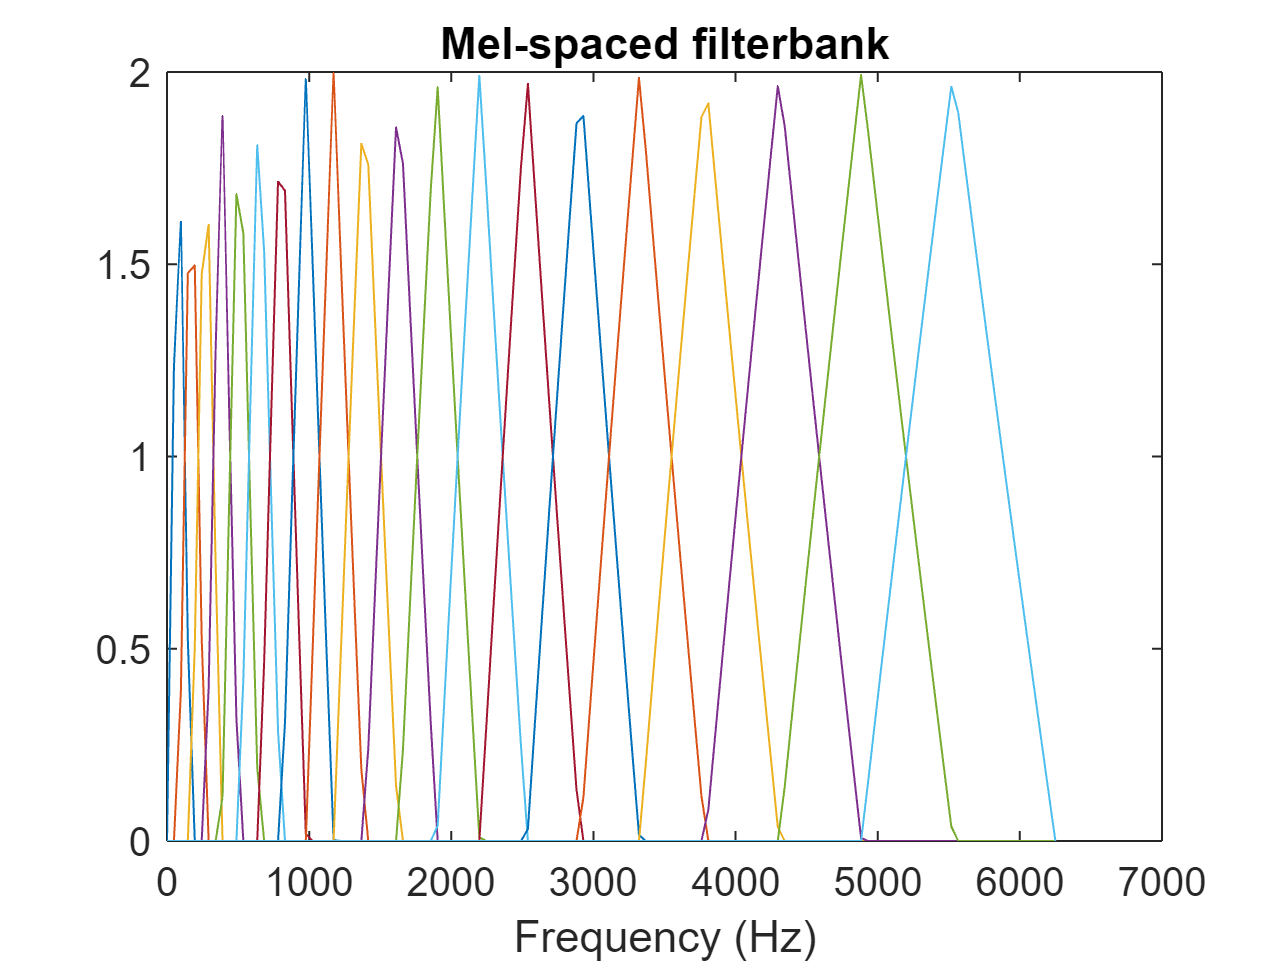

% melfb part
p = 20;
n = 256;
fs = Fs1;
m = melfb(p,n,fs);
plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');

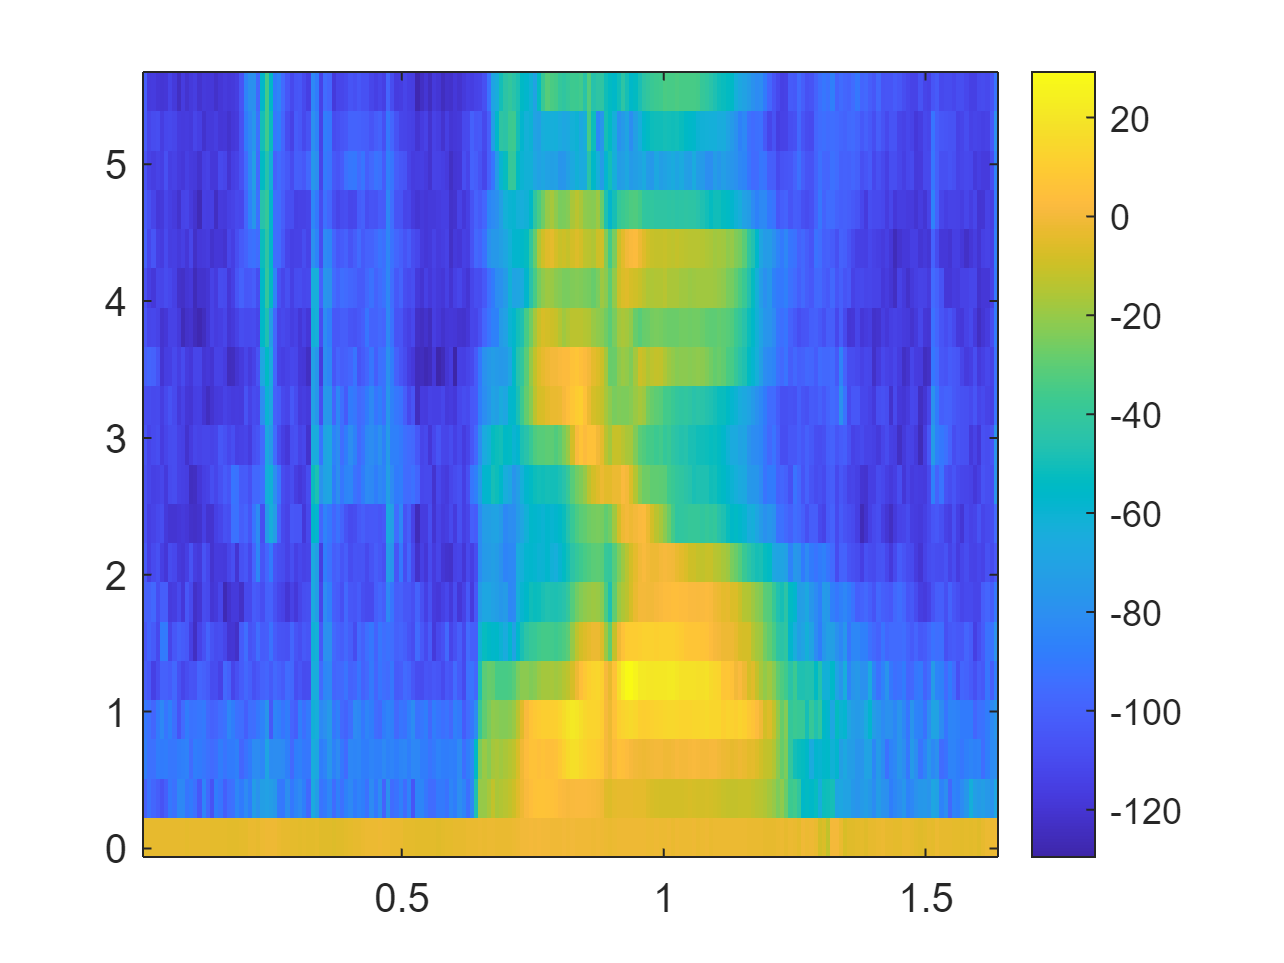

% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(n2-1:n)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some));
imagesc((T),(Ff/1000),some);
set(gca, 'YDir', 'normal');
view(2)
colorbar

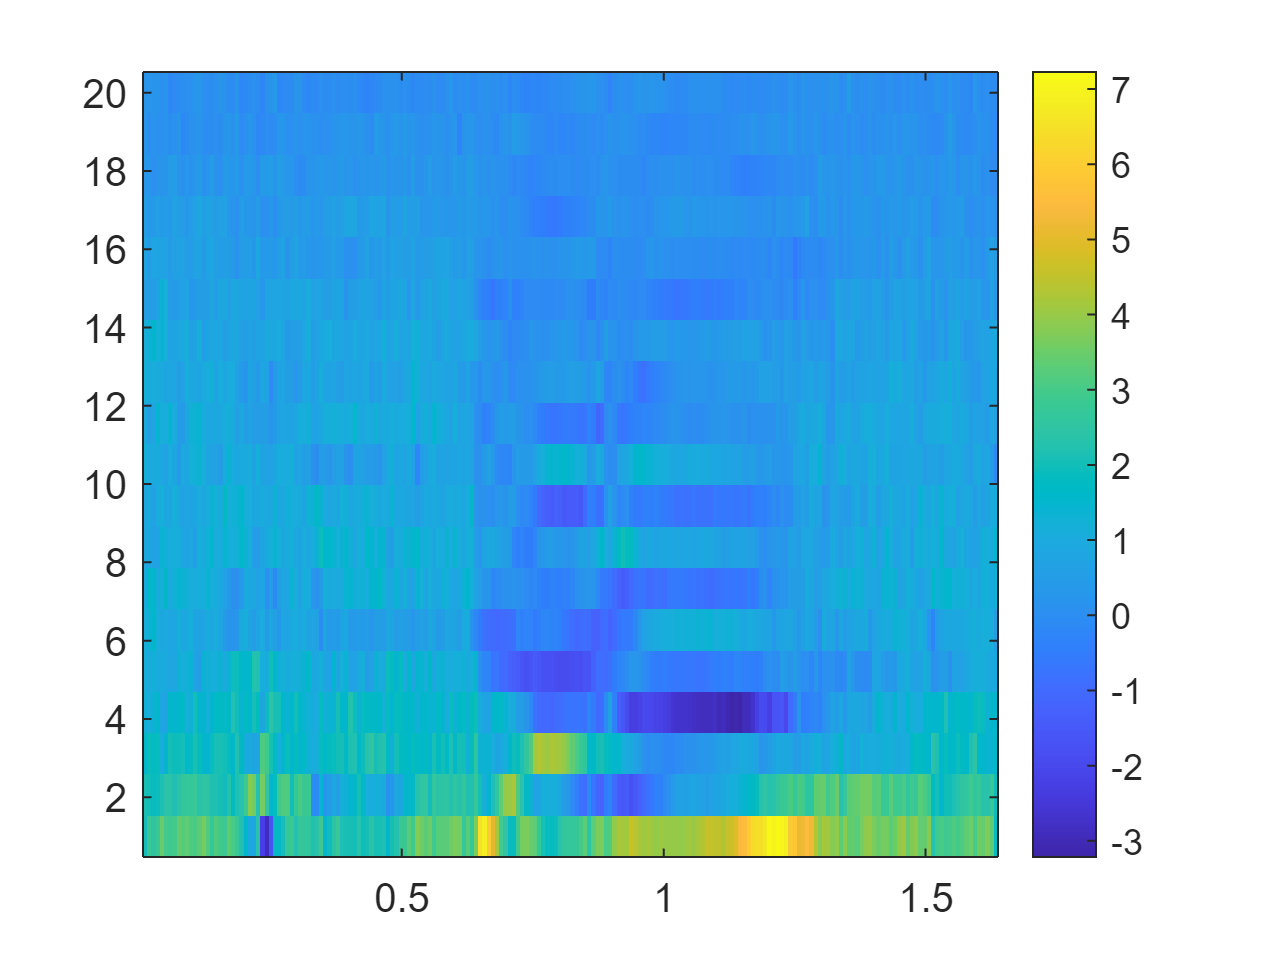

some = some / 20;
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(some(:,i));
    if i == 1
        y = [f(2:end)];
    else
        y = [y f(2:end)];
    end
end
%sdb = mag2db(abs(y));
y11 = y;
newf = 1:1:20;
imagesc(Tt,(newf)',y11);
set(gca, 'YDir', 'normal');
view(2)
colorbar

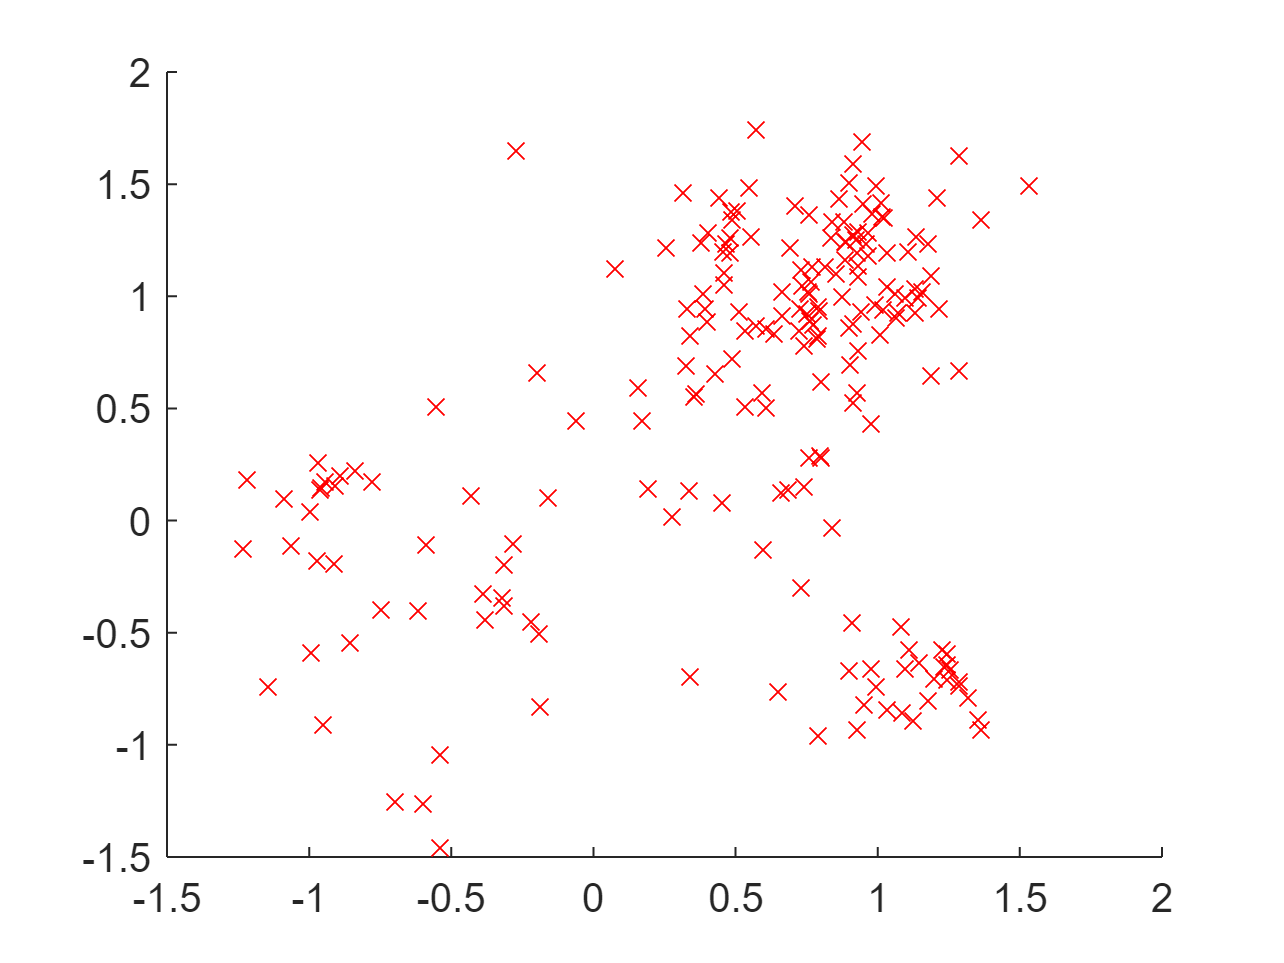

%end of dct part
scatter(y11(6,:),y11(7,:),'r','x')

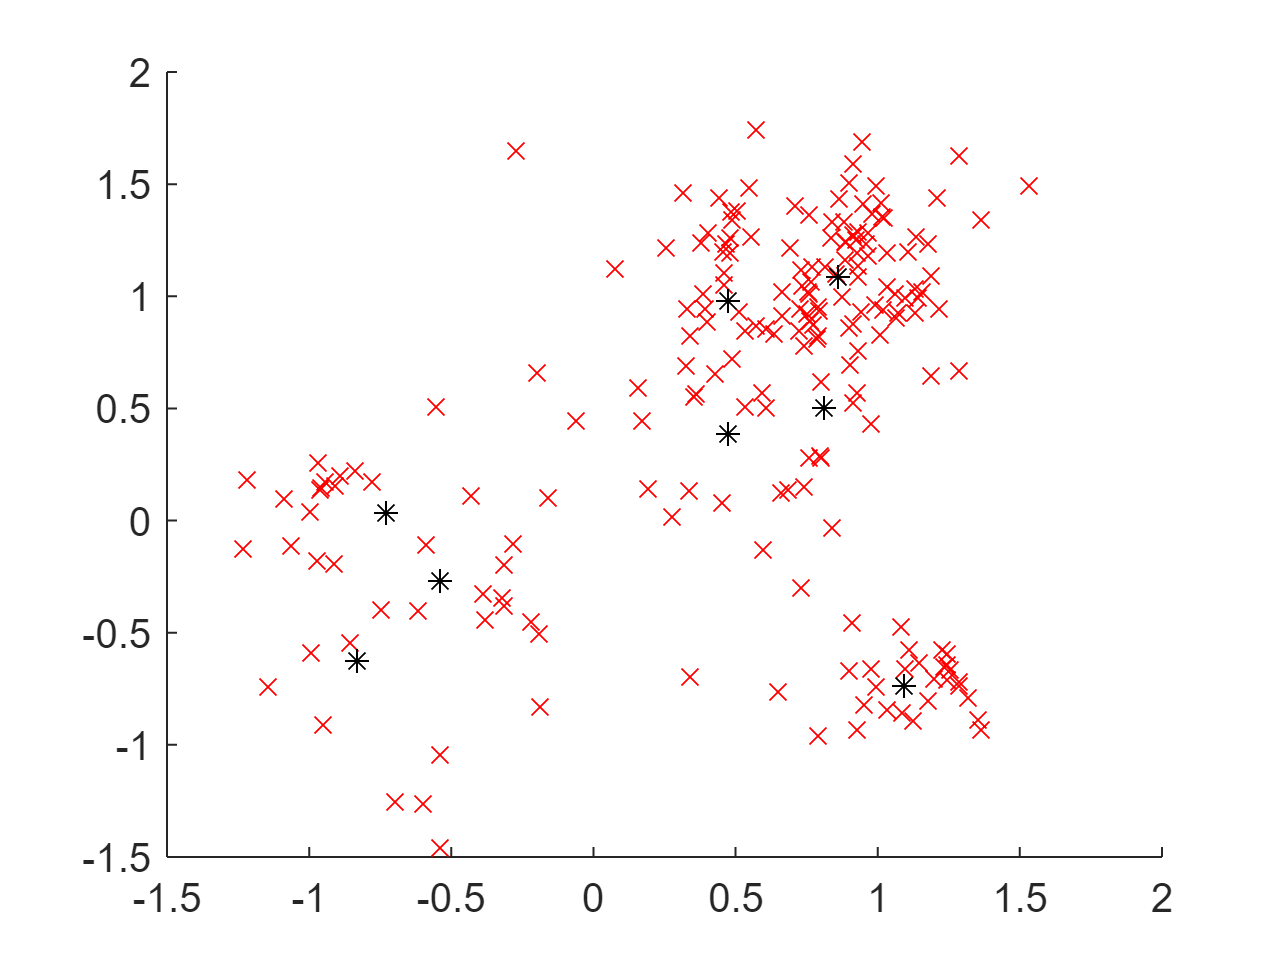

numCentroids = 8;
[dimensions,frames] = size(y11);
eplison = 0.001;
clusters1 = LBGAlgorithm(numCentroids,dimensions,frames,(y11)',eplison);
scatter(y11(6,:),y11(7,:),'r','x')
hold on;
scatter(clusters1(:,6),clusters1(:,7),'black','*')
hold off;